
clear; clc; close all
%% Radar parameters
c = physconst('LightSpeed'); %speed of light
BW = 50e6; %bandwidth
fc = 3e9; % carrier frequency
numADC = 256; % # of adc samples
numChirps = 256; % # of chirps per frame

numCPI = 10;
T = 10e-4; % PRI 
PRF = 1/T;
F = numADC/T; % sampling frequency
dt = 1/F; % sampling interval
slope = BW/T;
lambda = c/fc;

N = numChirps*numADC*numCPI; % total # of adc samples
t = linspace(0,T*numChirps*numCPI,N); % time axis, one frame
t_onePulse = 0:dt:dt*numADC-dt;

numTX = 4;
numRX = 4;

N_L=floor(2*fc/BW);
N_L=(mod(N_L, 2) == 0)*(N_L-1)+(mod(N_L, 2) == 1)*(N_L); % 扩展的虚拟阵列
N_L=1;
Vmax = lambda/(T*4); % Max Unamb velocity m/s


d_tx= lambda/2;
d_rx = numRX*d_tx; % dist. between rxs

% d_tx = 4*d_rx; % dist. between txs

% tr_vel=-d_tx/2/T;
tr_vel=0;







%% Targets

r1_radial = 300;
tar1_angle = -60;
r1_y = cosd(tar1_angle)*r1_radial;
r1_x = sind(tar1_angle)*r1_radial;
v1_radial = 0.1; % velocity 1
v1_y = cosd(tar1_angle)*v1_radial;
v1_x = sind(tar1_angle)*v1_radial;
r1 = [r1_x r1_y 0];

tar1_loc = zeros(length(t),3);
tar1_loc(:,1) = r1(1) + v1_x*t;
tar1_loc(:,2) = r1(2) + v1_y*t;


r2_radial = 400;
tar2_angle = 40;
r2_y = cosd(tar2_angle)*r2_radial;
r2_x = sind(tar2_angle)*r2_radial;
v2_radial = 0.1; % velocity 2
v2_y = cosd(tar2_angle)*v2_radial;
v2_x = sind(tar2_angle)*v2_radial;
r2 = [r2_x r2_y 0];

tar2_loc = zeros(length(t),3);
tar2_loc(:,1) = r2(1) + v2_x*t;
tar2_loc(:,2) = r2(2) + v2_y*t;

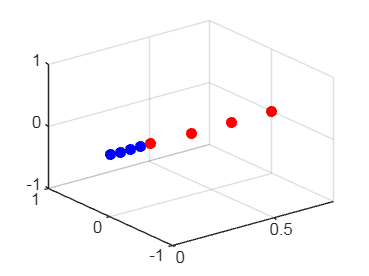


% tx_loc = cell(1,numTX);
% for i = 1:numTX
%    tx_loc{i} = [(i-1)*d_tx 0 0];
%    scatter3(tx_loc{i}(1),tx_loc{i}(2),tx_loc{i}(3),'b','filled')
%    hold on
% end

% rx_loc = cell(1,numRX);
% for i = 1:numRX
%    rx_loc{i} = [tx_loc{numTX}(1)+d_tx+(i-1)*d_rx 0 0];
%    scatter3(rx_loc{i}(1),rx_loc{i}(2),rx_loc{i}(3),'r','filled')
% end

tx_loc = cell(1,numTX);
tx_loc_t=cell(1,numTX);
for i = 1:numTX
   tx_loc{i} = [(i-1)*d_tx 0 0];
   tx_loc_t{i}=zeros(length(t),3);
   tx_loc_t{i}(:,1)=tr_vel*t+tx_loc{i}(1);

   scatter3(tx_loc{i}(1),tx_loc{i}(2),tx_loc{i}(3),'b','filled')
   hold on
end

rx_loc = cell(1,numRX);
rx_loc_t=cell(1,numTX);

for i = 1:numRX
   rx_loc{i} = [tx_loc{numTX}(1)+d_tx+(i-1)*d_rx 0 0];
   rx_loc_t{i}=zeros(length(t),3);
   rx_loc_t{i}(:,1)=tr_vel*t+rx_loc{i}(1);

   scatter3(rx_loc{i}(1),rx_loc{i}(2),rx_loc{i}(3),'r','filled')
end

%% TX

delays_tar1 = cell(numTX,numRX);
delays_tar2 = cell(numTX,numRX);

for i = 1:numTX
    for j = 1:numRX
        delays_tar1{i,j} = (vecnorm(tar1_loc-rx_loc_t{j},2,2) ...
                            +vecnorm(tar1_loc-tx_loc_t{i},2,2))/c; 
        delays_tar2{i,j} = (vecnorm(tar2_loc-rx_loc_t{j},2,2) ...
                            +vecnorm(tar2_loc-tx_loc_t{i},2,2))/c;
    end
end

r1_at_t = cell(numTX,numRX);
r2_at_t = cell(numTX,numRX);
tar1_angles = cell(numTX,numRX);
tar2_angles = cell(numTX,numRX);
tar1_velocities = cell(numTX,numRX);
tar2_velocities = cell(numTX,numRX);


%% Complex signal
phase = @(tx,fx) 2*pi*(fx.*tx+slope/2*tx.^2); % transmitted
phase2 = @(tx,fx,r,v) 2*pi*(2*fx*r/c+tx.*(2*fx*v/c + 2*slope*r/c)); % downconverted

% mixed1 = cell(numTX,numRX);
% mixed2 = cell(numTX,numRX);
mixed = cell(numTX,numRX);
for i = 1:numTX
    for j = 1:numRX
        disp(['Processing Channel: ' num2str(j) '/' num2str(numRX)]);
        for k = 1:numChirps*numCPI
            phase_t = phase(t_onePulse,fc);
            phase_1 = phase(t_onePulse-delays_tar1{i,j}(k*numADC),fc); % received
            phase_2 = phase(t_onePulse-delays_tar2{i,j}(k*numADC),fc);
            
            signal_t((k-1)*numADC+1:k*numADC) = exp(1j*phase_t);
            signal_1((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_1));
            signal_2((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_2));
        end
        mixed{i,j} = signal_1 + signal_2;
    end
end

Processing Channel: 1/4
Processing Channel: 2/4
Processing Channel: 3/4
Processing Channel: 4/4
Processing Channel: 1/4
Processing Channel: 2/4
Processing Channel: 3/4
Processing Channel: 4/4
Processing Channel: 1/4
Processing Channel: 2/4
Processing Channel: 3/4
Processing Channel: 4/4
Processing Channel: 1/4
Processing Channel: 2/4
Processing Channel: 3/4
Processing Channel: 4/4






fr1 = 2*r1(2)*slope/c; 
fr2 = 2*r2(2)*slope/c;
fd1 = 2*v1_radial*fc/c; % doppler freq
fd2 = 2*v2_radial*fc/c;
f_if1 = fr1 + fd1; % beat or IF freq
f_if2 = fr2 + fd2;

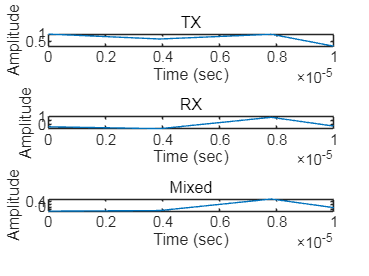


figure
subplot(3,1,1)
p1 = plot(t, real(signal_t));
title('TX')
xlim([0 0.1e-4])
xlabel('Time (sec)');
ylabel('Amplitude');
subplot(3,1,2)
p2 = plot(t, real(signal_1));
title('RX')
xlim([0 0.1e-4])
xlabel('Time (sec)');
ylabel('Amplitude');
subplot(3,1,3)
p3 = plot(t,real(mixed{i,j}));
title('Mixed')
xlim([0 0.1e-4])
xlabel('Time (sec)');
ylabel('Amplitude');

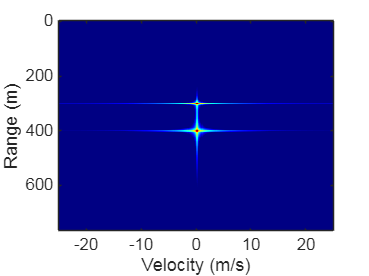


%% Post processing - 2-D FFT
% size(cat(3,mixed{:}))



RDC = reshape(cat(3,mixed{:}),numADC,numChirps*numCPI,numRX*numTX); % radar data cube

RDC_plus=zeros(numADC,(numChirps-(N_L-1))*numCPI,numRX*numTX+N_L-1);



for i = 1:numCPI
    RDC_plus(:,(1:(numChirps-(N_L-1)))+(i-1)*(numChirps-(N_L-1)), ...
                (N_L-1)/2+1:(N_L-1)/2+1+numRX*numTX-1)=...
        RDC(:, (((N_L-1)/2+1):(numChirps-(N_L-1)/2))+ ...
        (i-1)*(numChirps),:);
    for j = 1:(N_L-1)/2
        for k = 1:numChirps-(N_L-1)
            RDC_plus(:,k+(i-1)*(numChirps-(N_L-1)),(N_L-1)/2+1-j)=RDC(:,(k+(N_L-1)/2+j)+(numChirps*(i-1)),1);
            RDC_plus(:,k+(i-1)*(numChirps-(N_L-1)),(N_L-1)/2+1+numRX*numTX-1+j)=RDC(:,(k+(N_L-1)/2-j)+(numChirps*(i-1)),numRX*numTX);        
        end                
    end 
end
numChirps_new=(numChirps-(N_L-1));


DFmax = 1/2*PRF; % = Vmax/(c/fc/2); % Max Unamb Dopp Freq
dR = c/(2*BW); % range resol
Rmax = F*c/(2*slope); % TI's MIMO Radar doc
Rmax2 = c/2/PRF; % lecture 2.3
dV = lambda/(2*numChirps*T); % velocity resol, lambda/(2*framePeriod)

N_Dopp = numChirps_new; % length of doppler FFT
N_range = numADC; % length of range FFT
N_azimuth = numRX*numTX+N_L-1;
R = 0:dR:Rmax-dR; % range axis
V = linspace(-Vmax, Vmax, numChirps_new); % Velocity axis
ang_ax = -90:90; % angle axis


RDMs = zeros(numADC,numChirps_new,numTX*numRX+N_L-1,numCPI);
for i = 1:numCPI
    RD_frame = RDC_plus(:,(i-1)*numChirps_new+1:i*numChirps_new,:);
    RDMs(:,:,:,i) = fftshift(fft2(RD_frame,N_range,N_Dopp),2);
end




figure
imagesc(V,R,20*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1))))));
colormap(jet(256))
% set(gca,'YDir','normal')
clim = get(gca,'clim');
caxis([clim(1)/2 0])
xlabel('Velocity (m/s)');
ylabel('Range (m)');

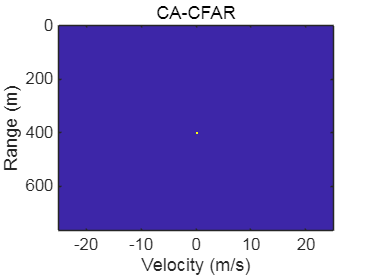


%% CA-CFAR

numGuard = 2; % # of guard cells
numTrain = numGuard*2; % # of training cells
P_fa = 1e-5; % desired false alarm rate 
SNR_OFFSET = -5; % dB
RDM_dB = 10*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1)))));

[RDM_mask, cfar_ranges, cfar_dopps, K] = ca_cfar(RDM_dB, numGuard, numTrain, P_fa, SNR_OFFSET);
cfar_ranges_real=(cfar_ranges-1)*3;
figure
h=imagesc(V,R,RDM_mask);
xlabel('Velocity (m/s)')
ylabel('Range (m)')
title('CA-CFAR')

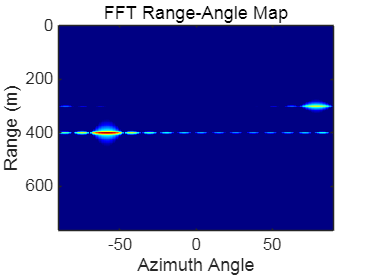


%% Angle Estimation - FFT

rangeFFT = fft(RDC_plus(:,1:numChirps_new,:),numChirps_new);

angleFFT = fftshift(fft(rangeFFT,length(ang_ax),3),3);
range_az = squeeze(sum(angleFFT,2)); % range-azimuth map

figure
colormap(jet)
imagesc(ang_ax,R,20*log10(abs(range_az)./max(abs(range_az(:))))); 
xlabel('Azimuth Angle')
ylabel('Range (m)')
title('FFT Range-Angle Map')
set(gca,'clim', [-35, 0])

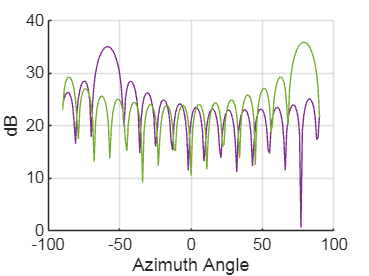


doas = zeros(K,181); % direction of arrivals
figure
hold on; grid on;
for i = 1:K
    doas(i,:) = fftshift(fft(rangeFFT(cfar_ranges(i),cfar_dopps(i),:),181));
    plot(ang_ax,10*log10(abs(doas(i,:))))
end
xlabel('Azimuth Angle')
ylabel('dB')


% figure
% hold on; grid on;
% for i = 1:K
%     plot(ang_ax,abs(doas(i,:)))
% end
% xlabel('Azimuth Angle')



%% Angle Estimation - MUSIC Pseudo Spectrum

d = 0.5;
M = numCPI; % # of snapshots

for k=1:length(ang_ax)
        a1(:,k)=exp(-1i*2*pi*(d*(0:numRX*numTX+N_L-1-1)'*sin(ang_ax(k).'*pi/180)));
end


% % 假设 a1 是阵列因子矩阵，RDC_plus 是信号矩阵，numChirps_new 是 chirp 数量，numADC 是每个短 chirp 的长度
% % 角度轴 ang_ax 是从 -90 到 90 度
% 
% % 初始化方向图的响应数组
% angles = -90:1:90;  % 角度范围 [-90, 90]，角度步长为1度
% numAngles = length(angles);
% response = zeros(1, numAngles);  % 初始化方向图响应数组
% 
% % 对每个角度计算阵列响应
% for k = 1:numAngles
%     % 假设 RDC_plus 是信号矩阵，首先获取 Range-Doppler 处理后的信号
%     % 我们这里只取一个CPI的数据进行处理（可以调整为不同的CPI索引）
%     signal = RDC_plus(:, (1:numChirps_new), :);  % 获取CPI相关的数据
% 
%     % 使用阵列因子 a1 和信号信号结合。根据你提供的信息，假设我们对 RDMs 进行加权和
%     % 这里假设 `a1(:, k)` 和信号进行加权计算
%     response(k) = abs(sum(a1(:, k) .* signal(:)));  % 这里通过乘积计算阵列的响应
% end
% 
% % 归一化响应并转换为 dB 单位
% response_dB = 20 * log10(response / max(response));
% 
% % 绘制方向图
% figure;
% plot(angles, response_dB);
% xlabel('Angle (Degrees)');
% ylabel('Response (dB)');
% title('Array Radiation Pattern');
% grid on;






for i = 1:K
    Rxx = zeros(numRX*numTX+N_L-1,numRX*numTX+N_L-1);
    for m = 1:M
       A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,m));
       Rxx = Rxx + 1/M * (A*A');
    end

    [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
    [D, I] = sort(diag(D),'descend');
    Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
    Qs = Q(:,1); % Get the signal eigenvectors
    Qn = Q(:,2:end); % Get the noise eigenvectors

    for k=1:length(ang_ax)
        music_spectrum(i,k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
        % music_spectrum(i,k)=(1)/(a1(:,k)'*(Qn*Qn')*a1(:,k));
    end
end

figure
hold on 
grid on
title('MUSIC Spectrum')
xlabel('Angle in degrees')

for k = 1:K
    plot(ang_ax,log10(abs(music_spectrum(k,:))));
end



    A = reshape(squeeze(RDMs(:,1:10,:,1)),numADC*10,numRX*numTX+N_L-1);

    Rxx = (A'*A);

    [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
    [D, I] = sort(diag(D),'descend');
    Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
    Qs = Q(:,1); % Get the signal eigenvectors
    Qn = Q(:,3:end); % Get the noise eigenvectors

    for k=1:length(ang_ax)
        music_spectrum(i,k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
        % music_spectrum(i,k)=(1)/(a1(:,k)'*(Qn*Qn')*a1(:,k));
    end


figure
hold on 
grid on
title('MUSIC Spectrum')
xlabel('Angle in degrees')


    plot(ang_ax,log10(abs(music_spectrum(2,:))));



%% Point Cloud

[~, I] = max(music_spectrum(2,:));
angle1 = ang_ax(I);
[~, I] = max(music_spectrum(1,:));
angle2 = ang_ax(I);

coor1 = [cfar_ranges_real(2)*sind(angle1) cfar_ranges_real(2)*cosd(angle1) 0];
coor2 = [cfar_ranges_real(1)*sind(angle2) cfar_ranges_real(1)*cosd(angle2) 0];
figure
hold on;
title('3D Coordinates (Point Cloud) of the targets')
scatter3(coor1(1),coor1(2),coor1(3),100,'m','filled','linewidth',9)
scatter3(coor2(1),coor2(2),coor2(3),100,'b','filled','linewidth',9)
xlabel('Range (m) X')
ylabel('Range (m) Y')
zlabel('Range (m) Z')


%% MUSIC Range-AoA map
rangeFFT = fft(RDC_plus);
for i = 1:N_range
    Rxx = zeros(numRX*numTX+N_L-1,numRX*numTX+N_L-1);
    for m = 1:M
       A = squeeze(sum(rangeFFT(i,(m-1)*numChirps_new+1:m*numChirps_new,:),2));
       Rxx = Rxx + 1/M * (A*A');
    end
%     Rxx = Rxx + sqrt(noise_pow/2)*(randn(size(Rxx))+1j*randn(size(Rxx)));
    [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
    [D, I] = sort(diag(D),'descend');
    Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
    Qs = Q(:,1); % Get the signal eigenvectors
    Qn = Q(:,2:end); % Get the noise eigenvectors

    for k=1:length(ang_ax)
        music_spectrum2(k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
    end
    
    range_az_music(i,:) = music_spectrum2;
end

figure
colormap(jet)
imagesc(ang_ax,R,20*log10(abs(range_az_music)./max(abs(range_az_music(:))))); 
xlabel('Azimuth')
ylabel('Range (m)')
title('MUSIC Range-Angle Map')
clim = get(gca,'clim');


%% Angle Estimation - Compressed Sensing

numTheta = length(ang_ax); % divide FOV into fine grid
B = a1; % steering vector matrix or dictionary, also called basis matrix

figure
hold on; grid on;
title('Angle Estimation with Compressed Sensing')
xlabel('Azimuth')
ylabel('dB')
for i = 1:K
    A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,1));
    cvx_begin
        variable s(numTheta) complex; %alphax(numTheta,1) phix(numTX*numRX,numTheta)...

        minimize(norm(s,1))
        norm(A-B*s,2) <= 1;
    cvx_end
    cvx_status
    cvx_optval

    plot(ang_ax,10*log10(abs(s)))
end

